※7chに最適化

※REMのthletholdは手動→下位1割のEMGに

clearvars;
timerVal.process = tic;

## Set constants

### Flags & file names

Flag.plotAll = 1;       
Flag.saveData = 0;
Flag.saveFigs = 0;
Flag.Th_emg_auto = 0;% Sleep vs wake EMG threshold

Defaultpath_rawdata = 'D:\data\解析\';% a folder for original binary data
Defaultpath_dataanalysis = 'D:\data\解析\';% a folder for data analysis
%E:\kato\data\
Filename_raw = "20211213_KAT276_FP\01.bin";
Filename_mat = Filename_raw;

%Defaultpath_rawdata = "D:\ES\Projects\TRN_sleepawake\data\";
%Filename_raw = "PV_YC\SNT260\test\01_20191108.bin";
%Filename_mat = "PV_YC\SNT260\test\01_20191108";

### Figure display

Col.eeg = [0 0 0]/255; Col.emg = [153 0 0]/255; Col.other = [128 128 128]/255;Col.grey = [230 230 230]/255;
Col.ex = [0 0 255]/255; Col.cfp = [0 204 255]/255; Col.yfp = [91 255 0]/255;
disp_scale.eeg = 10^6; disp_scale.emg = 10^6;% for display in uV

### LabView recording

% ePhysFPvideo_TDT256_3.0
% EEG/EMGのみの時はChanel数を変更する
ColumNum.eeg = 1; ColumNum.emg = 2;
ColumNum.yfp = 3; ColumNum.cfp = 4;ColumNum.stim = 5; ColumNum.FretLight = 6; ColumNum.Sync = 7;% all column index for a raw data
SR_ori = 1000; % original rampling rate
RecGain = [1000, 1000]; % amp gain for eeg and emg

### Spectrogram analysis for eeg & emg

movingwin = [10 10];%[4,4];[2, 0.1]
% eeg
params.fpass = [1 15];% Amplifier filter setting: 1-300 Hz
params.tapers = [2 3];
params.pad = 0;
params.trialave = 0;
params.err = 0;
params.Fs = SR_ori;
% emg
params_emg.fpass = [10 100]; % Amp filter 10-300 Hz
params_emg.tapers = [2 3];
params_emg.pad = 0;
params_emg.trialave = 0;
params_emg.err = 0;
params_emg.Fs = SR_ori;

### Hypnogram classification

% Target frequencies
Freq.DL = [1 4];% [1 4]; % delta, normalized to power 1-25 Hz; NREM = delta/theta > 0.4
Freq.TH = [6 9];%[6 9]; % theta, normalized to delta power; REM = delta/theta < 0.4
Freq.Nm = [1 25]; % freq of interest (Murayama 2016 Sci paper); theta/delta is traditional.
Freq.SG = [9 16]; % sigma
%Freq.eeg = [1 100];
Freq.emg = [10 100]; %Fisher/Peirson., 2012, J Biol Rhythms.


## Set a table variable

% T_data contains all data necessary for further analysis.
T = table(Filename_raw, Filename_mat);

T.ch = numel(fieldnames(ColumNum));% ch = 7
T.Properties.VariableDescriptions{'ch'} = 'number of recording channels';

T.SR_ori = SR_ori;
T.Properties.VariableUnits{'SR_ori'} = 'Hz';
T.Properties.VariableDescriptions{'SR_ori'} = 'original sampling rate';

T.SR_anal = 100;
T.Properties.VariableUnits{'SR_anal'} = 'Hz';
T.Properties.VariableDescriptions{'SR_anal'} = 'sampling rate for analysis';

T.span = 99;
T.Properties.VariableUnits{'span'} = 'points';
T.Properties.VariableDescriptions{'span'} ='points for moving average';

T.splineDur = 120;
T.Properties.VariableUnits{'splineDur'} = 'sec';

T.FLbleachDur = 5;% sec
T.Properties.VariableUnits{'FLbleachDur'} = 'sec';
T.Properties.VariableDescriptions{'FLbleachDur'} =...
    'duration to compare the first & last fluorescence intentisy';

T.movingwin = movingwin;
T.params_eeg = params;
T.params_emg = params_emg;

T.RecGain = RecGain;% Amplifier gains for EEG & EMG
T.Properties.VariableDescriptions{'RecGain'} = 'EEG, EMG';

## Load data

try
    raw_data = readmulti_DBL(fullfile(Defaultpath_rawdata, T.Filename_raw), T.ch);
    %raw_data_temp = readmulti_DBL(fullfile(Defaultpath_rawdata, T.Filename_raw), T.ch);

catch ME
    fprintf('=== ERROR! readmulti_DBL failed: %s ===', T.Filename_raw)
    return
end
fprintf('Loaded: %s', T.Filename_raw);

Loaded: 20210218_KAT193_FP\01.bin

%tt_ori = (1:length(raw_data(:,ColumNum.eeg)))'/T.SR_ori;% in sec
%raw_data = gpuArray(raw_data_temp);clear raw_data_temp;

% FP: Smoothed raw data
tt_ori = (1:length(raw_data(:,ColumNum.yfp)))'/T.SR_ori;% in sec
Data.Y_sm = smooth(raw_data(:, ColumNum.yfp), T.span, 'moving');
Data.C_sm = smooth(raw_data(:, ColumNum.cfp), T.span, 'moving');

## Calculation

### FP data: decimated & detrended traces

T.tt_anal = {(1:length(Data.Y_sm))'/T.SR_ori};
T.Y_sm_deci = {Data.Y_sm};
T.C_sm_deci = {Data.C_sm};
T.Y_sm_deci_det = {Detrend_spline(T.Y_sm_deci{1}, T.SR_ori*T.splineDur, 'median', 1)};

T.C_sm_deci_det = {Detrend_spline(T.C_sm_deci{1}, T.SR_ori*T.splineDur, 'median', 1)};


[Y_raw, trend_.Y] = Detrend_spline(Data.Y_sm, T.SR_ori*T.splineDur, 'median', 1);

[C_raw, trend_.C] = Detrend_spline(Data.C_sm, T.SR_ori*T.splineDur, 'median', 1);


tt_anal = (1:length(Data.Y_sm))'/T.SR_ori;
YC_sm_deci_det = Y_raw./C_raw;

T.YC_sm_deci_det = {YC_sm_deci_det};
clear temp_Y_sm_deci temp_C_sm_deci

### EEG & EMG data: multi taper spectrogram

[Sp.eeg, Tsp.eeg, Fsp.eeg] = mtspecgramc(...
    detrend(raw_data(:, ColumNum.eeg))/T.RecGain(1)*disp_scale.eeg, movingwin, params);
[Sp.emg, Tsp.emg, Fsp.emg] = mtspecgramc(...
    detrend(raw_data(:, ColumNum.emg))/T.RecGain(2)*disp_scale.emg, movingwin, params_emg);
% Sp: 900x91 double, time x freq; Fsp: 1x91 double, freq
Tsp.dur_eeg = seconds(Tsp.eeg');% class duration
Tsp.dur_emg = seconds(Tsp.emg');

Freq_idx.DL = Freq.DL(1) <= Fsp.eeg & Fsp.eeg <= Freq.DL(2);
Freq_idx.TH = Freq.TH(1) <= Fsp.eeg & Fsp.eeg <= Freq.TH(2);
Freq_idx.Nm = Freq.Nm(1) <= Fsp.eeg & Fsp.eeg <= Freq.Nm(2);
Freq_idx.SG = Freq.SG(1) <= Fsp.eeg & Fsp.eeg <= Freq.SG(2);
%Freq_idx.eeg = Freq.eeg(1) <= Fsp.eeg & Fsp.eeg <= Freq.eeg(2);
Freq_idx.emg = Freq.emg(1) <= Fsp.emg & Fsp.emg <= Freq.emg(2);

Pw.DL = mean(Sp.eeg(:,Freq_idx.DL), 2);
Pw.TH = mean(Sp.eeg(:,Freq_idx.TH), 2);
Pw.Nm = mean(Sp.eeg(:,Freq_idx.Nm), 2);
Pw.SG = mean(Sp.eeg(:,Freq_idx.SG), 2);
%Pw.eeg = mean(Sp.eeg(:,Freq_idx.eeg), 2);
Pw.TDratio = Pw.TH./Pw.DL;
Pw.SDratio = Pw.SG./Pw.DL;
Pw.emg = mean(Sp.emg(:,Freq_idx.emg), 2);

%if Flag.Th_emg_auto % 3x of mean of lower 10% of EMG Pow
%    Pw.emg_sorted = sort(Pw.emg);
%    Th.Hypno_emg = mean(Pw.emg_sorted(1:round(length(Pw.emg_sorted)*0.1)))*3;% 3x of lower 10%
%end

% REMの閾値を設定
Pw.emg_sorted = sort(Pw.emg);
Th.Hypno_REM = mean(Pw.emg_sorted(1:round(length(Pw.emg_sorted)*0.1)));

### Hypnogram

% Manual setting for thresholds
Th.Hypno_eeg = mean(Pw.DL);
Th.TDratio = mean(Pw.TDratio);
%Th.TDratio = mean(Pw.TDratio) + std(Pw.TDratio);%2.5;% ThetaDeltaRatio Murayama 2016 Science
Th.Hypno_emg = mean(Pw.emg);%100;% uV^2
%Th.Hypno_emg = mean(Pw.emg) + std(Pw.emg);
Idx.NREM = Pw.TDratio <= Th.TDratio & Pw.emg < Th.Hypno_emg & Pw.DL >= Th.Hypno_eeg;%Miyamoto/Murayama_2016_Science
%Idx.NREM = Pw.emg < Th.Hypno_emg & Pw.DL >= Th.Hypno_eeg;%Miyamoto/Murayama_2016_Science
Idx.REM  = Pw.TDratio > Th.TDratio & Pw.emg < Th.Hypno_REM; %Yüzgeç/Huber_2018 CBでは2 * std
Idx.wake = ~(Idx.NREM | Idx.REM);
%Idx.wake = Pw.emg >= Th.Hypno_emg & Pw.DL < Th.Hypno_eeg | ~(Idx.NREM | Idx.REM);% & Pw.TDratio > Th.TDratio_eeg;

Label.wake = 3;
Label.NREM = 2;
Label.REM = 1;
slmap = zeros(1,size(Tsp.eeg,2));
%slmap(Idx.wake) = Label.wake;
slmap(Idx.wake) = Label.wake;
slmap(Idx.NREM) = Label.NREM;
slmap(Idx.REM) = Label.REM;

tempslmap.ori = slmap;

% No direct transition from wake to REM
while any(diff([Label.NREM, slmap]) == (Label.REM - Label.wake))
    slmap(diff([Label.NREM, slmap]) == (Label.REM - Label.wake)) = Label.wake;
end
tempslmap.noWR = slmap;

% No flipping. Wake-NREM-Wake. NREM-REM-Wake
minus_index = find(diff([slmap(1), slmap]) == -1);
plus_index  = find(diff([slmap(1), slmap]) == +1);
Logical_index = ismember(minus_index + 1, plus_index);
target_index = minus_index(Logical_index);
slmap(target_index) = slmap(target_index - 1);
tempslmap.noWNWflip = slmap;

% No flipping. NREM-Wake-NREM. REM-NREM-REM
minus_index = find(diff([slmap(1), slmap]) == -1);
plus_index  = find(diff([slmap(1), slmap]) == +1);
Logical_index = ismember(plus_index + 1, minus_index);
target_index = plus_index(Logical_index);
slmap(target_index) = slmap(target_index - 1);
tempslmap.noNWN = slmap;

% sleep stage ratio
sleepRatio.wake = sum(slmap == Label.wake)/length(slmap);
sleepRatio.NREM = sum(slmap == Label.NREM)/length(slmap);
sleepRatio.REM = sum(slmap == Label.REM)/length(slmap);

[xb_all, yb_all] = stairs(Tsp.eeg, slmap);% for plot stairs with distinct colors
xb.wake = xb_all; xb.wake(yb_all ~= Label.wake) = NaN;
xb.NREM  = xb_all; xb.NREM(yb_all ~= Label.NREM) = NaN;
xb.REM = xb_all; xb.REM(yb_all ~= Label.REM) = NaN;
yb.wake = yb_all; yb.wake(yb_all ~= Label.wake) = NaN;
yb.NREM = yb_all; yb.NREM(yb_all ~= Label.NREM) = NaN;
yb.REM = yb_all; yb.REM(yb_all ~= Label.REM) = NaN;
toc(timerVal.process)

経過時間は 12.560478 秒です。


#### 合算図

#### (EMG spectrogram記載)

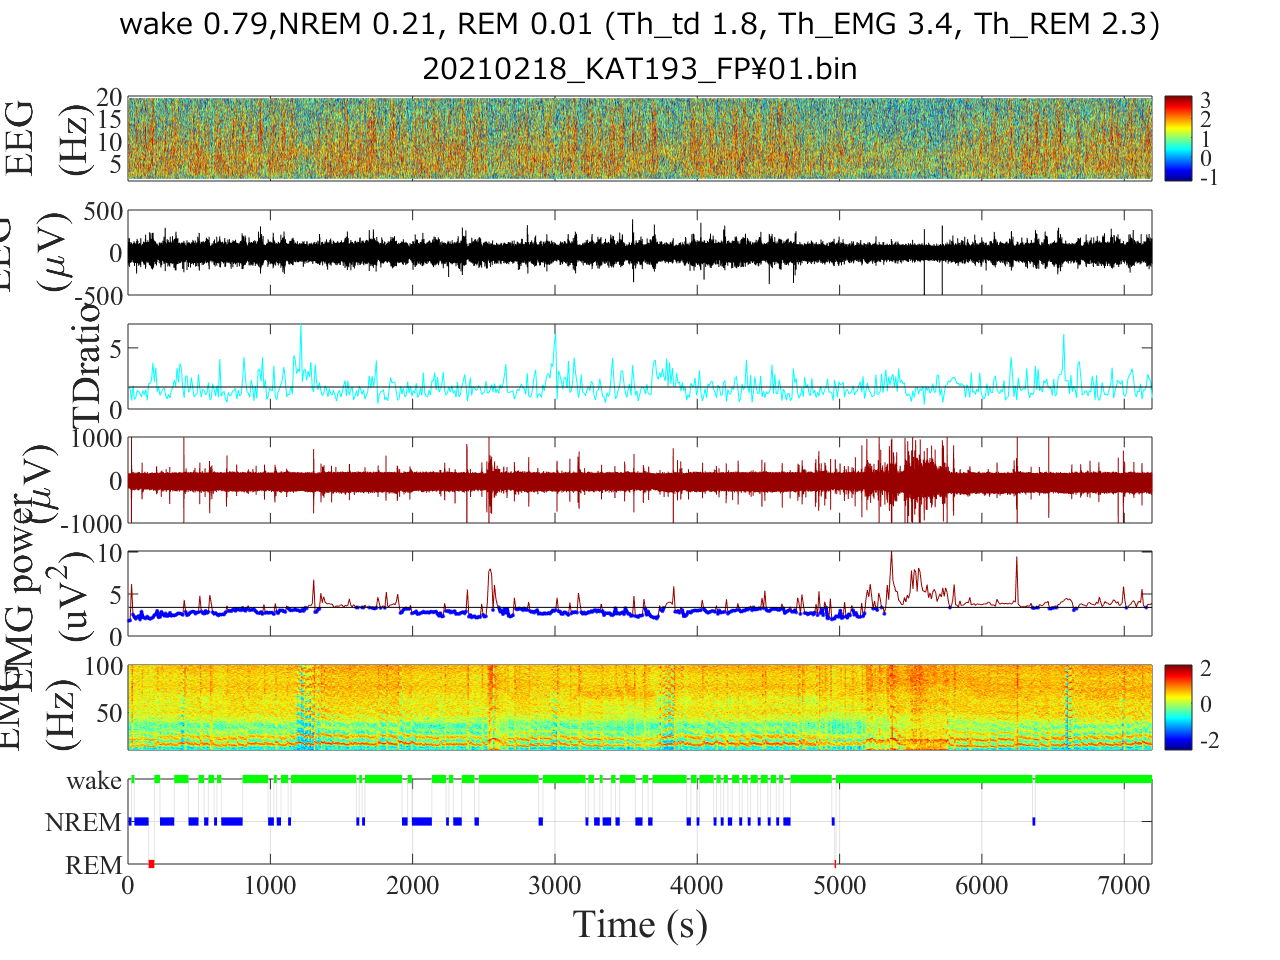

movingwin2 = [2 0.1];
params2.fpass = [1 20];
params2.tapers = [2 3];
params2.pad = 0;
params2.trialave = 0;
params2.err = 0;
params2.Fs = SR_ori;
[Sp2.eeg, Tsp2.eeg, Fsp2.eeg] = mtspecgramc(...
    detrend(raw_data(:, ColumNum.eeg))/T.RecGain(1)*disp_scale.eeg, movingwin2, params2);

if 1 || Flag.plotAll
    sleepscore = figure;
    
    ax_sleepscore = subaxis(7,1,1, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    plot_sleepscore = pcolor(Tsp2.eeg, Fsp2.eeg, log10(Sp2.eeg')); shading interp
    colormap jet; caxis auto;
    ttemp = ax_sleepscore.Position;
    colorbar, ax_sleepscore.Position = ttemp;
    
    ax_sseeg = subaxis(7,1,2, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    plot_sseeg = plot(tt_ori, detrend(raw_data(:,ColumNum.eeg))/T.RecGain(1)*disp_scale.eeg, 'Color', Col.eeg, 'DisplayName', 'eeg');
    
    ax_sm_td = subaxis(7,1,3, 'SpacingVertical', 0.03);
    h.plot_sm_td = plot(Tsp.eeg, Pw.TDratio, 'c',  'DisplayName', 'TDratio');
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    line([Tsp.eeg(1) Tsp.eeg(end)], [Th.TDratio Th.TDratio], 'Color', 'k', 'HandleVisibility', 'off')
    %line([Tsp.eeg(1) Tsp.eeg(end)], [mean(Pw.TDratio) mean(Pw.TDratio)], 'Color', 'b', 'HandleVisibility', 'off')
        
    ax_ssemg = subaxis(7,1,4, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    plot_ssemg = plot(tt_ori, detrend(raw_data(:,ColumNum.emg))/T.RecGain(2)*disp_scale.emg, 'Color', Col.emg, 'DisplayName', 'emg');
    
    ax_emg_pow = subaxis(7,1,5, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    
    plot_emg_pow = plot(Tsp.emg, Pw.emg, 'Color', Col.emg, 'DisplayName', 'emg');
    temp_Pw_emg = Pw.emg;
    temp_Pw_emg(Pw.emg > Th.Hypno_emg) = NaN;
    plot_emg_pow_low = plot(Tsp.emg, temp_Pw_emg, '-b', 'marker', '.', 'linewidth', 2, 'HandleVisibility', 'off');
    line([Tsp.emg(1) Tsp.emg(end)], [Th.Hypno_emg Th.Hypno_emg], 'Color', 'k', 'HandleVisibility', 'off');
    
    ax_emg_spectrogram = subaxis(7,1,6, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    plot_emg_spectrogram = pcolor(Tsp.emg, Fsp.emg, log10(Sp.emg')); shading flat
    colormap jet; caxis auto;
    ttemp = ax_emg_spectrogram.Position;
    colorbar, ax_emg_spectrogram.Position = ttemp;
    
        ax_ssscore = subaxis(7,1,7, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    
    plot(xb_all, yb_all, '-', 'linewidth', 0.1, 'color', Col.grey);
    plot(xb.wake, yb.wake, 'Color', 'g', 'linewidth', 5);
    plot(xb.NREM, yb.NREM, 'Color', 'b', 'linewidth', 5);
    plot(xb.REM, yb.REM, 'Color', 'r', 'linewidth', 5);
    grid on;
    
    set(ax_ssscore, 'YTick', [1 2 3], 'YTicklabel', {'REM', 'NREM','wake'});
    set(ax_sleepscore, 'ylim', [params2.fpass(1) params2.fpass(2)]);
    set(ax_emg_spectrogram, 'ylim', [params_emg.fpass(1) params_emg.fpass(2)]);
    set(ax_sseeg, 'ylim', [-500 500]);
    set(ax_ssemg, 'ylim', [-1000 1000]);
    set([ax_sleepscore, ax_sseeg, ax_ssemg,ax_emg_spectrogram], 'XTickLabel', []);
    %set(ax_sleepscore.Title, 'String', sprintf('AW %2.2f, QW %2.2f, NREM %2.2f, IS %2.2f, REM %2.2f (Th_td %2.1f, Th_EMG %2.1f)\n%s',...
    %    sleepRatio.AW,sleepRatio.QW, sleepRatio.NREM, sleepRatio.IS, sleepRatio.REM, Th.TDratio, Th.Hypno_emg, Filename_mat));
    set(ax_sleepscore.Title, 'String', sprintf('wake %2.2f,NREM %2.2f, REM %2.2f (Th_td %2.1f, Th_EMG %2.1f, Th_REM %2.1f)\n%s',...
        sleepRatio.wake,sleepRatio.NREM, sleepRatio.REM, Th.TDratio, Th.Hypno_emg,Th.Hypno_REM, Filename_mat));
    set([ax_emg_pow, ax_sseeg, ax_ssemg, ax_sm_td], 'XTickLabel', []);
    ax_emg_pow.YLabel.String = 'EMG power\newline     (uV^2)';
    ax_sleepscore.YLabel.String = 'EEG\newline(Hz)';
    ax_sseeg.YLabel.String = 'EEG\newline(\muV)';
    ax_ssemg.YLabel.String = 'EMG\newline(\muV)';
    ax_sm_td.YLabel.String = 'TDratio';
    ax_sleepscoreemg.YLabel.String = 'EEG\newline(Hz)';
     ax_emg_spectrogram.YLabel.String = 'EMG\newline(Hz)';
    ax_ssscore.XLabel.String = 'Time (s)';
    linkaxes([ax_sleepscore, ax_sseeg, ax_ssemg, ax_ssscore, ax_emg_pow, ax_emg_spectrogram,ax_sm_td], 'x');
    xlim([0 Tsp.eeg(end)]);
end

#### FRETあり

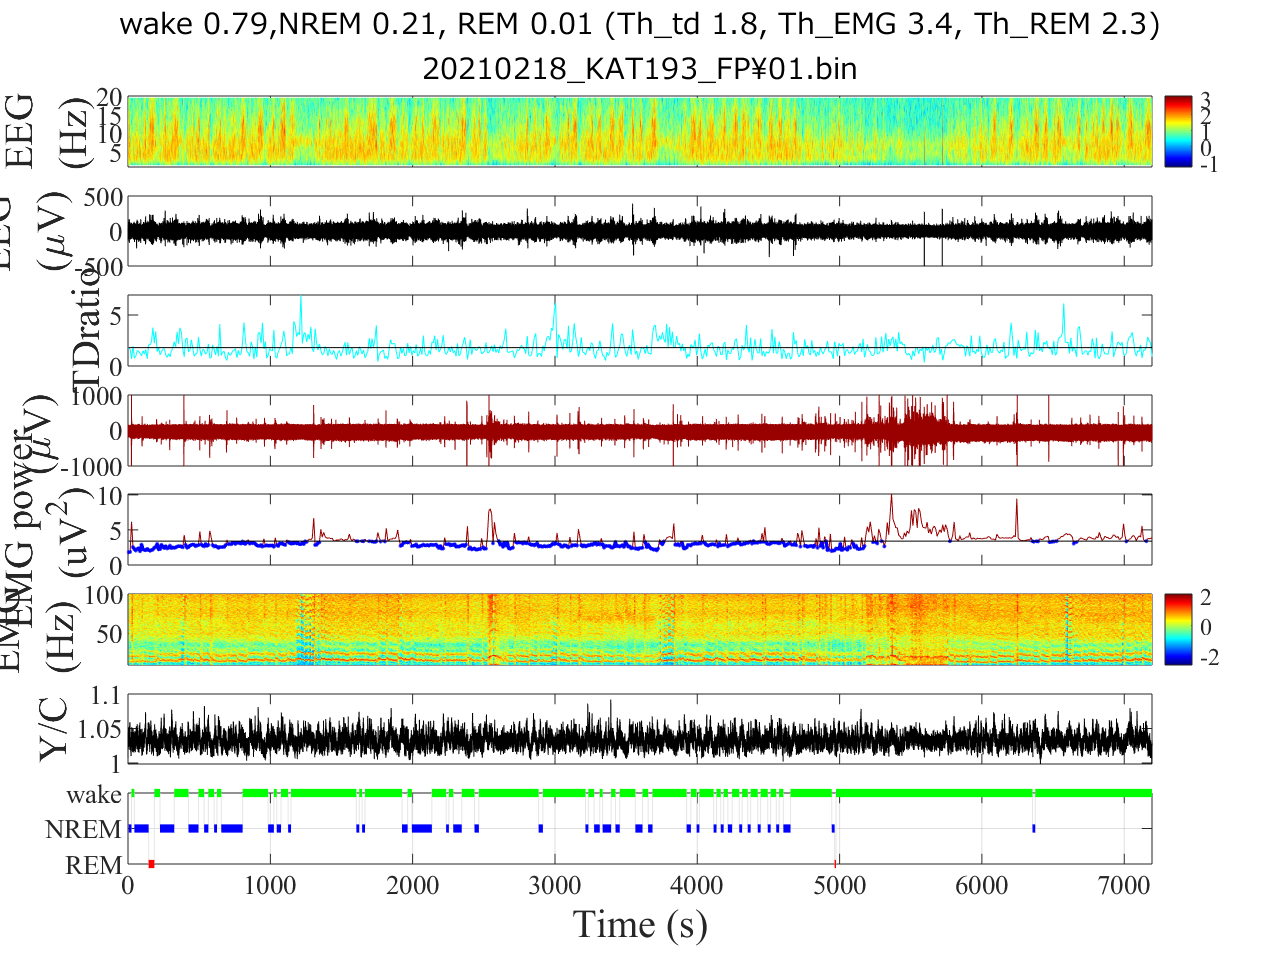


if 1 || Flag.plotAll
    sleepscore = figure;
    
    ax_sleepscore = subaxis(8,1,1, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    plot_sleepscore = pcolor(Tsp2.eeg, Fsp2.eeg, log10(Sp2.eeg')); shading flat
    colormap jet; caxis auto;
    ttemp = ax_sleepscore.Position;
    colorbar, ax_sleepscore.Position = ttemp;
    
    ax_sseeg = subaxis(8,1,2, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    plot_sseeg = plot(tt_ori, detrend(raw_data(:,ColumNum.eeg))/T.RecGain(1)*disp_scale.eeg, 'Color', Col.eeg, 'DisplayName', 'eeg');
    
    ax_sm_td = subaxis(8,1,3, 'SpacingVertical', 0.03);
    h.plot_sm_td = plot(Tsp.eeg, Pw.TDratio, 'c',  'DisplayName', 'TDratio');
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    line([Tsp.eeg(1) Tsp.eeg(end)], [Th.TDratio Th.TDratio], 'Color', 'k', 'HandleVisibility', 'off')
    %line([Tsp.eeg(1) Tsp.eeg(end)], [mean(Pw.TDratio) mean(Pw.TDratio)], 'Color', 'b', 'HandleVisibility', 'off')
        
    ax_ssemg = subaxis(8,1,4, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    plot_ssemg = plot(tt_ori, detrend(raw_data(:,ColumNum.emg))/T.RecGain(2)*disp_scale.emg, 'Color', Col.emg, 'DisplayName', 'emg');
    
    ax_emg_pow = subaxis(8,1,5, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    
    plot_emg_pow = plot(Tsp.emg, Pw.emg, 'Color', Col.emg, 'DisplayName', 'emg');
    temp_Pw_emg = Pw.emg;
    temp_Pw_emg(Pw.emg > Th.Hypno_emg) = NaN;
    plot_emg_pow_low = plot(Tsp.emg, temp_Pw_emg, '-b', 'marker', '.', 'linewidth', 2, 'HandleVisibility', 'off');
    line([Tsp.emg(1) Tsp.emg(end)], [Th.Hypno_emg Th.Hypno_emg], 'Color', 'k', 'HandleVisibility', 'off');
    
    ax_emg_spectrogram = subaxis(8,1,6, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title', 12, 'fontsize_axis', 16)); hold on;
    plot_emg_spectrogram = pcolor(Tsp.emg, Fsp.emg, log10(Sp.emg')); shading flat
    colormap jet; caxis auto;
    ttemp = ax_emg_spectrogram.Position;
    colorbar, ax_emg_spectrogram.Position = ttemp;
    
    ax_sm_deci_yc = subaxis(8,1,7, 'SpacingVertical', 0.03);
    h.plot_sm_deci_yc = plot(tt_anal, YC_sm_deci_det, 'k',  'DisplayName', 'YFP sm deci');
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    
        ax_ssscore = subaxis(8,1,8, 'SpacingVertical', 0.03);
    setFig(struct('fontsize_title',12, 'fontsize_axis',16)); hold on;
    
    plot(xb_all, yb_all, '-', 'linewidth', 0.1, 'color', Col.grey);
    plot(xb.wake, yb.wake, 'Color', 'g', 'linewidth', 5);
    plot(xb.NREM, yb.NREM, 'Color', 'b', 'linewidth', 5);
    plot(xb.REM, yb.REM, 'Color', 'r', 'linewidth', 5);
    grid on;
    
    set(ax_ssscore, 'YTick', [1 2 3], 'YTicklabel', {'REM', 'NREM','wake'});
    set(ax_sleepscore, 'ylim', [params2.fpass(1) params2.fpass(2)]);
    set(ax_emg_spectrogram, 'ylim', [params_emg.fpass(1) params_emg.fpass(2)]);
    set(ax_sseeg, 'ylim', [-500 500]);
    set(ax_ssemg, 'ylim', [-1000 1000]);
    set([ax_sleepscore, ax_sseeg, ax_ssemg,ax_emg_spectrogram], 'XTickLabel', []);
    %set(ax_sleepscore.Title, 'String', sprintf('AW %2.2f, QW %2.2f, NREM %2.2f, IS %2.2f, REM %2.2f (Th_td %2.1f, Th_EMG %2.1f)\n%s',...
    %    sleepRatio.AW,sleepRatio.QW, sleepRatio.NREM, sleepRatio.IS, sleepRatio.REM, Th.TDratio, Th.Hypno_emg, Filename_mat));
    set(ax_sleepscore.Title, 'String', sprintf('wake %2.2f,NREM %2.2f, REM %2.2f (Th_td %2.1f, Th_EMG %2.1f, Th_REM %2.1f)\n%s',...
        sleepRatio.wake,sleepRatio.NREM, sleepRatio.REM, Th.TDratio, Th.Hypno_emg, Th.Hypno_REM, Filename_mat));
    set([ax_emg_pow, ax_sseeg, ax_ssemg, ax_sm_td, ax_sm_deci_yc], 'XTickLabel', []);
    ax_emg_pow.YLabel.String = 'EMG power\newline     (uV^2)';
    ax_sleepscore.YLabel.String = 'EEG\newline(Hz)';
    ax_sseeg.YLabel.String = 'EEG\newline(\muV)';
    ax_ssemg.YLabel.String = 'EMG\newline(\muV)';
    ax_sm_deci_yc.YLabel.String = 'Y/C';
    ax_sm_td.YLabel.String = 'TDratio';
    ax_sleepscoreemg.YLabel.String = 'EEG\newline(Hz)';
     ax_emg_spectrogram.YLabel.String = 'EMG\newline(Hz)';
    ax_ssscore.XLabel.String = 'Time (s)';
    linkaxes([ax_sleepscore, ax_sseeg, ax_ssemg, ax_ssscore, ax_emg_pow, ax_emg_spectrogram,ax_sm_td, ax_sm_deci_yc], 'x');
    xlim([0 Tsp.eeg(end)]);
end

自動判別した結果から自動でYCのmean, S.D.を計算

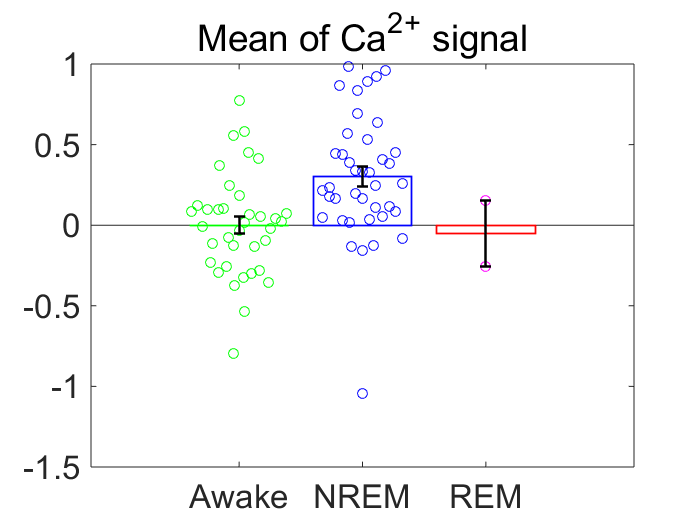

%awake
xb.wake(isnan(xb.wake))=0; %xb.wake(wakeのindexを含む)のNaNを0に置換
da = xb.wake(find(xb.wake>0)); %wakeのindexのみを持ってくる
dda = find(diff(da)>10); %wakeのidxの中で10秒(moving window)以上ずれているものを持ってくる=diffの際にidxが-1されるので、あるawakeの塊の最後の秒数を持ってくることになる
Da = vertcat(da(dda),max(da)); %これがe-idx
DDa = vertcat(min(da),da(dda+1)); %これがs-idx
Xa = [DDa Da];
DDA = round(DDa*10^3,0);
DA = round(Da*10^3,0);
%nrem
xb.NREM(isnan(xb.NREM))=0; 
dn = xb.NREM(find(xb.NREM>0)); 
ddn = find(diff(dn)>10);
Dn = vertcat(dn(ddn),max(dn)); %これがe-idx
DDn = vertcat(min(dn),dn(ddn+1)); %これがs-idx
Xn = [DDn Dn];
DDN = round(DDn*10^3,0);
DN = round(Dn*10^3,0);
%rem
xb.REM(isnan(xb.REM))=0; 
dr = xb.REM(find(xb.REM>0)); 
ddr = find(diff(dr)>10);
Dr = vertcat(dr(ddr),max(dr)); %これがe-idx
DDr = vertcat(min(dr),dr(ddr+1)); %これがs-idx
Xr = [DDr Dr];
DDR = round(DDr*10^3,0);
DR = round(Dr*10^3,0);

%figure;
%for n=1:(numel(DDA));
%  plot((DDA(n):DA(n)),YC_sm_deci_det(DDA(n):DA(n)),'g');
%  hold on
%end
%for n=1:(numel(DDN));
%   plot((DDN(n):DN(n)),YC_sm_deci_det(DDN(n):DN(n)),'b');
%   hold on
%end
%for n=1:(numel(DDR));
%   plot((DDR(n):DR(n)),YC_sm_deci_det(DDR(n):DR(n)),'r');
%   hold on
%end

mda_p = zeros(1,numel(DA));
sda_p = zeros(1,numel(DA));
mda = zeros(1,numel(DA));
sda = zeros(1,numel(DA));
mdn = zeros(1,numel(DN));
sdn = zeros(1,numel(DN));
mdr = zeros(1,numel(DR));
sdr = zeros(1,numel(DR));


for n=1:(numel(DDA))
 mda_p(n) = mean(YC_sm_deci_det(DDA(n):DA(n)));
 sda_p(n) = std(YC_sm_deci_det(DDA(n):DA(n)));
end
mdap = mean(mda_p);
sdap = mean(sda_p);
Yy = (YC_sm_deci_det-mdap)/sdap;

for n=1:(numel(DDA))
 mda(n) = mean(Yy(DDA(n):DA(n)));
 sda(n) = std(Yy(DDA(n):DA(n)));
end
for n=1:(numel(DDN))
 mdn(n) = mean(Yy(DDN(n):DN(n)));
 sdn(n) = std(Yy(DDN(n):DN(n)));
end
 if DDr ~= 0
     for n=1:(numel(DDR))
         mdr(n) = mean(Yy(DDR(n):DR(n)));
         sdr(n) = std(Yy(DDR(n):DR(n)));
     end
 else 
     mdr = NaN;
     sdr = NaN;
 end
 
 

Mda = mean(mda);
Mdn = mean(mdn);
Mdr = mean(mdr);
Sda = mean(sda);
Sdn = mean(sdn);
Sdr = mean(sdr);
er1 = std(mda)/sqrt(numel(mda));
er2 = std(mdn)/sqrt(numel(mdn));
er3 = std(mdr)/sqrt(numel(mdr));
eer1 = std(sda)/sqrt(numel(sda));
eer2 = std(sdn)/sqrt(numel(sdn));
eer3 = std(sdr)/sqrt(numel(sdr));

figure;
yy = [Mda Mdn Mdr];
b = bar(yy,'FaceColor','none','EdgeColor','Flat','LineWidth',1);
p_S = {mda, mdn, mdr};
plotSpread(p_S, 'binWidth',0.5,'distributionColors', {'g','b','m'},'distributionMarkers',{'o'}, 'spreadFcn',{'xp',[]})
b.CData(1,:) = [0 1 0];
b.CData(2,:) = [0 0 1];
b.CData(3,:) = [1 0 0];
xticks([1:3]);
xticklabels({'Awake','NREM','REM'});
title('Mean of Ca^2^+ signal');
hold on

errorbar(1, Mda, er1, 'k', 'LineWidth', 1.5);
errorbar(2, Mdn, er2, 'k', 'LineWidth', 1.5);
errorbar(3, Mdr, er3, 'k', 'LineWidth', 1.5);

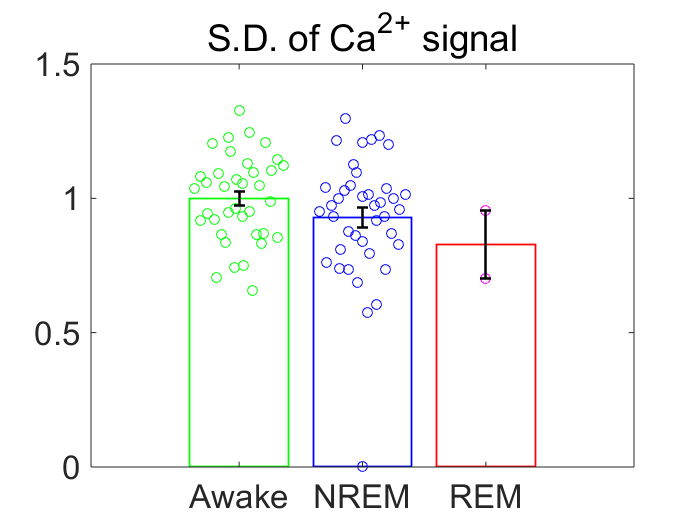


figure;
y = [Sda Sdn Sdr];
b = bar(y,'FaceColor','none','EdgeColor','Flat','LineWidth',1);
pp_S = {sda, sdn, sdr};
plotSpread(pp_S, 'binWidth',0.5,'distributionColors', {'g','b','m'},'distributionMarkers',{'o'}, 'spreadFcn',{'xp',[]})
b.CData(1,:) = [0 1 0];
b.CData(2,:) = [0 0 1];
b.CData(3,:) = [1 0 0];
xticks([1:3]);
xticklabels({'Awake','NREM','REM'});
title('S.D. of Ca^2^+ signal');
hold on

errorbar(1, Sda, eer1, 'k', 'LineWidth', 1.5);
errorbar(2, Sdn, eer2, 'k', 'LineWidth', 1.5);
errorbar(3, Sdr, eer3, 'k', 'LineWidth', 1.5);


[h,p] = ttest2(mda,mdn)

h = 1

p = 3.9511e-04

[h,p] = ttest2(mda,mdr)

h = 0

p = 0.8226

[h,p] = ttest2(mdn,mdr)

h = 0

p = 0.2123